%Q3
clear; 
syms L1 L2 L3 L4 L5 L6 L7 L8 L9 x y z u
eqn1= L1*x+L2*y==0;
eqn2= L3*x+L4*y+L5*z==0;
eqn3= L6*x+L7*y+L8*z==L9*u;
sol=solve(eqn1,eqn2,eqn3,x,y,z); 
g=sol.y/u; %solution for q3
%Q4 part 1
syms s sigma b xbar ybar zbar x y z u
eqn1= (s+sigma)*x+(-sigma)*y==0;
eqn2= zbar*x+(s+1)*y+xbar*z==0;
eqn3= ybar*x+xbar*y+(-s-b)*z==b*u;
sol=solve(eqn1,eqn2,eqn3,x,y,z); 
G=sol.y/u; %my solution for first part of q4
[numG,denG] = numden(G);
numG=coeffs(numG,s);
denG=coeffs(denG,s);
denG=denG(end:-1:1);
%Q4 part 2
p=RR_roots(denG);
f(b,sigma,xbar,ybar,zbar)=p;
q=f(1,4,0,0,-48); %poles for first nominal solution
r=f(1,4,sqrt(47),sqrt(47),-1); %poles for for second nominal solution
%this one is the example I used since it simplifies to having a positive
%real part of 0.332
d=f(1,4,-sqrt(47),-sqrt(47),-1); %poles for third nominal solution
%each pole has a positive real part, so unstable
%Q5 done on paper
%here's Q6
t=0:0.1:10;
A=-(4)*sqrt(47)/(r(1)*r(2)*r(3));
B=(r(1)+4)*sqrt(47)/(r(1)*(r(1)-r(2))*(r(1)-r(3)));
C=(r(2)+4)*sqrt(47)/(r(2)*(r(2)-r(1))*(r(2)-r(3)));
D=(r(3)+4)*sqrt(47)/(r(3)*(r(3)-r(2))*(r(3)-r(2))); %coeff for plot 1
y1=A+B*exp(r(1)*t)+C*exp(r(2)*t)+D*exp(r(3)*t);
plot(t,y1);

hold on
E=(4)*sqrt(47)/(d(1)*d(2)*d(3));
F=-(d(1)+4)*sqrt(47)/(d(1)*(d(1)-d(2))*(d(1)-d(3)));
H=-(d(2)+4)*sqrt(47)/(d(2)*(d(2)-d(1))*(d(2)-d(3)));
I=-(d(3)+4)*sqrt(47)/(d(3)*(d(3)-d(2))*(d(3)-d(2))); %coeff for plot 2
y2=E+F*exp(d(1)*t)+H*exp(d(2)*t)+I*exp(d(3)*t);
plot(t,y2)

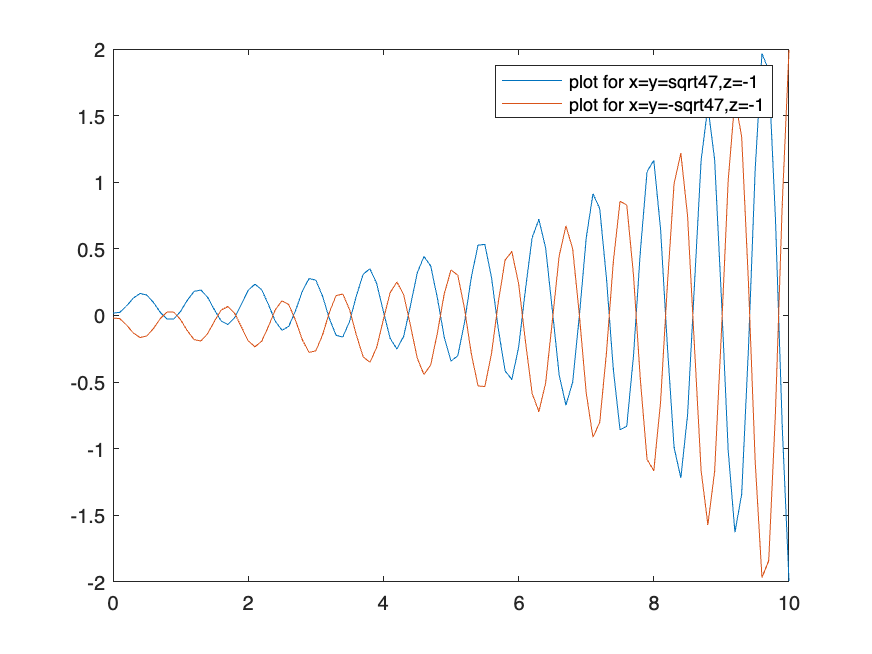

hold off
legend('plot for x=y=sqrt47,z=-1','plot for x=y=-sqrt47,z=-1')